**MCP LOOP FOR LQR PROBLEM**

import casadi.*
opti = casadi.Opti();

dt = 0.1;% sampling time

Nmpc = 100;% ocp iterations
T = Nmpc*dt; % time horizon
%constraints
Umin = -1000;
Umax = 1000;
Qdotmin = -3*pi/2;
Qdotmax = 3*pi/2;

x0 = [-5; -4; 0; 0] %initial state

x0 =     -5
    -4
     0
     0


xf = [pi/2; 0; 0; 0] %final state

xf =     1.5708
         0
         0
         0



N           =   10;
nx          =   4;
nu          =   2;
xsim           =   zeros(nx,N+1);
usim           =   zeros(nu,N);
xsim(:,1)      =   x0;
Xsol        =   repmat(x0,1,Nmpc+1);
Usol        =   repmat([0;0],1,Nmpc);
X_state = [];
U_state = [];
%MPC loop
for k = 1:10
    disp(k);
    x0 = xsim(:, k);
    [f, Xsol, Usol] = OCPloop(x0, xf, dt, opti, Nmpc, Xsol, Usol);
    usim(:, k) = Usol(:, 10); %prediction upto 10th iterate
    %xsim(:, k+1) = xsim(:, k) + dt*f(xsim(:,1), usim(:, 1));
    xsim(:, k+1) = Xsol(:, 10) + dt*f(Xsol(:, 10), Usol(:, 10));
    X_state = [X_state, Xsol(:, 1:10)];
    U_state = [U_state, Usol(:, 1:10)];
    Xsol = Xsol(:, 11:end);
    Usol = Usol(:, 11:end);
    Nmpc = Nmpc -10; %reducing the ocp horizon every iteration
end

     1




******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     2004
Number of nonzeros in inequality constraint Jacobian.:    40200
Number of nonzeros in Lagrangian Hessian.............:     1508

Total number of variables............................:      604
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality c

     2



This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     3808
Number of nonzeros in inequality constraint Jacobian.:    72780
Number of nonzeros in Lagrangian Hessian.............:     2358

Total number of variables............................:     1148
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      768
Total number of inequality constraints...............:    72780
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:    72780
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.4050590e+04 1.83e-01 1.53e-09  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

     3



This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     5412
Number of nonzeros in inequality constraint Jacobian.:    98540
Number of nonzeros in Lagrangian Hessian.............:     3108

Total number of variables............................:     1632
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1092
Total number of inequality constraints...............:    98540
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:    98540
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.3799647e+04 1.83e-01 2.30e-10  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

     4



This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     6816
Number of nonzeros in inequality constraint Jacobian.:   118280
Number of nonzeros in Lagrangian Hessian.............:     3758

Total number of variables............................:     2056
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1376
Total number of inequality constraints...............:   118280
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:   118280
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.3562122e+04 1.83e-01 2.31e-10  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

     5



This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     8020
Number of nonzeros in inequality constraint Jacobian.:   132800
Number of nonzeros in Lagrangian Hessian.............:     4308

Total number of variables............................:     2420
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1620
Total number of inequality constraints...............:   132800
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:   132800
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.3417280e+04 1.83e-01 2.20e-10  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

     6



This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     9024
Number of nonzeros in inequality constraint Jacobian.:   142900
Number of nonzeros in Lagrangian Hessian.............:     4758

Total number of variables............................:     2724
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1824
Total number of inequality constraints...............:   142900
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:   142900
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.3232001e+04 1.83e-01 1.64e-10  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

     7



This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     9828
Number of nonzeros in inequality constraint Jacobian.:   149380
Number of nonzeros in Lagrangian Hessian.............:     5108

Total number of variables............................:     2968
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1988
Total number of inequality constraints...............:   149380
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:   149380
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.2136697e+04 1.83e-01 5.06e-11  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

     8



This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:    10432
Number of nonzeros in inequality constraint Jacobian.:   153040
Number of nonzeros in Lagrangian Hessian.............:     5358

Total number of variables............................:     3152
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     2112
Total number of inequality constraints...............:   153040
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:   153040
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.1494511e+04 1.83e-01 2.52e-11  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

     9



This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:    10836
Number of nonzeros in inequality constraint Jacobian.:   154680
Number of nonzeros in Lagrangian Hessian.............:     5508

Total number of variables............................:     3276
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     2196
Total number of inequality constraints...............:   154680
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:   154680
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.0975914e+04 1.83e-01 7.39e-12  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

    10



This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:    11040
Number of nonzeros in inequality constraint Jacobian.:   155100
Number of nonzeros in Lagrangian Hessian.............:     5558

Total number of variables............................:     3340
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     2240
Total number of inequality constraints...............:   155100
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:   155100
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  1.2813068e+04 1.83e-01 1.47e-11  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

**FORWARD KINEMATICS**

X_state = [X_state, xsim(:, 11)] % appending the last state

X_state =    -5.0000   -5.0000   -4.9932   -4.9810   -4.9643   -4.9438   -4.9200   -4.8934   -4.8644   -4.8335   -4.8012   -4.7681   -4.7348   -4.7020   -4.6705   -4.6409   -4.6139   -4.5898   -4.5691   -4.5520   -4.5386   -4.5290   -4.5231   -4.5208   -4.5220   -4.5266   -4.5347   -4.5459   -4.5604   -4.5780   -4.5984   -4.6213   -4.6464   -4.6729   -4.7004   -4.7281   -4.7554   -4.7815   -4.8058   -4.8279   -4.8473   -4.8638   -4.8773   -4.8878   -4.8954   -4.9003   -4.9028   -4.9030   -4.9011   -4.8972
   -4.0000   -4.0000   -3.9843   -3.9525   -3.9044   -3.8399   -3.7594   -3.6634   -3.5531   -3.4299   -3.2962   -3.1545   -3.0080   -2.8604   -2.7153   -2.5764   -2.4472   -2.3306   -2.2290   -2.1442   -2.0775   -2.0299   -2.0019   -1.9939   -2.0061   -2.0386   -2.0914   -2.1643   -2.2570   -2.3690   -2.4994   -2.6467   -2.8090   -2.9836   -3.1670   -3.3554   -3.5445   -3.7296   -3.9066   -4.0718   -4.2221   -4.3553   -4.4699   -4.5650   -4.6401   -4.6950   -4.7297   -4.7442   -4.738

l1 = 0.5;
l2 = 0.5;
q1 = X_state(1,:);
q2 = X_state(2,:);
% forward kinematics
x = l1*cos(q1) + l2*cos(q1 + q2);
y = l1*sin(q1) + l2*sin(q1 + q2);

**PLOTS**

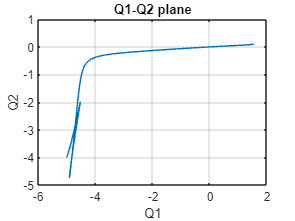

figure(1);
clf(1);
plot(q1', q2');
grid on;
hold on;
xlabel("Q1");
ylabel("Q2");
title('Q1-Q2 plane');
hold off;

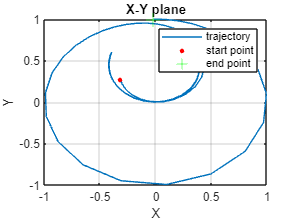


figure(2);
clf(2);
plot(x', y');
grid on;
hold on;
xlabel("X");
ylabel("Y");
plot(x(1), y(1), 'r.', 'MarkerSize', 10);  % Start point
plot(x(end), y(end), 'g+', 'MarkerSize', 10);  % End point
legend('trajectory', 'start point', 'end point')
title('X-Y plane');
hold off; 

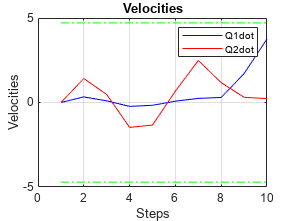


figure(3);
clf(3);
plot(xsim(3, :)', 'b');
hold on;
plot(xsim(4, :)', 'r');
grid on;
plot(1:N+1, Qdotmin*ones(N+1,1), '-.g');
plot(1:N+1, Qdotmax*ones(N+1,1), '-.g');
xlabel("Steps");
ylabel("Velocities");
legend('Q1dot', 'Q2dot');
xlim([0 N]);
title('Velocities');
hold off;

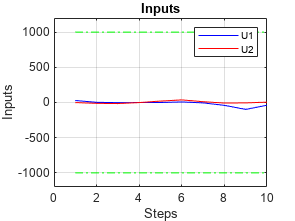


% Plot Inputs
figure(4);
clf(4);
plot(usim(1, :)', 'b');
hold on;
plot(usim(2, :)', 'r');
plot(1:N, Umin*ones(N,1), '-.g');
plot(1:N, Umax*ones(N,1), '-.g');
grid on;
xlabel("Steps");
ylabel("Inputs");
ylim([-1200 1200]);
xlim([0 N]);
legend('U1', 'U2');
title('Inputs');

**OCP LOOP FUNCTION**

function [f, Xsol, Usol] = OCPloop(x0, xf, dt, opti, Nmpc, Xsol, Usol)
    
    b1 = 200.0;
    b2 = 50.0;
    b3 = 23.5;
    b4 = 25.0;
    b5 = 122.5;
    c1 = -25.0;
    g1 = 784.8;
    g2 = 245.3;
    
    Q = 1e0*eye(4);
    R = 1e0*eye(2);
        
    X = opti.variable(4, Nmpc+1); %states over time
    U = opti.variable(2, Nmpc); % control inputs over time

    f = @(X, U) [X(3);
    X(4);
    -(b5*U(1) - b3*U(2) - b5*g1*cos(X(1)) - b4*U(2)*cos(X(2)) + b3*g2*cos(X(1) + X(2)) - b5*g2*cos(X(1) + X(2)) + b4*g2*cos(X(1) + X(2))*cos(X(2)) + b3*c1*X(3)^2*sin(X(2)) + b5*c1*X(4)^2*sin(X(2)) + b4*c1*X(3)^2*cos(X(2))*sin(X(2)) + 2*b5*c1*X(3)*X(4)*sin(X(2)))/(b4^2*cos(X(2))^2 - b1*b5 + b3^2 - b2*b5*cos(X(2)) + 2*b3*b4*cos(X(2)));
    (b3*U(1) - b1*U(2) - b3*g1*cos(X(1)) - b2*U(2)*cos(X(2)) + b4*U(1)*cos(X(2)) + b1*g2*cos(X(1) + X(2)) - b3*g2*cos(X(1) + X(2)) + b2*g2*cos(X(1) + X(2))*cos(X(2)) - b4*g2*cos(X(1) + X(2))*cos(X(2)) - b4*g1*cos(X(1))*cos(X(2)) + b1*c1*X(3)^2*sin(X(2)) + b3*c1*X(4)^2*sin(X(2)) + b2*c1*X(3)^2*cos(X(2))*sin(X(2)) + b4*c1*X(4)^2*cos(X(2))*sin(X(2)) + 2*b3*c1*X(3)*X(4)*sin(X(2)) + 2*b4*c1*X(3)*X(4)*cos(X(2))*sin(X(2)))/(b4^2*cos(X(2))^2 - b1*b5 + b3^2 - b2*b5*cos(X(2)) + 2*b3*b4*cos(X(2)))];

    Umin = -1000;
    Umax = 1000;
    Qdotmin = -3*pi/2;
    Qdotmax = 3*pi/2;
    opti.subject_to(X(:,1)==x0);
    
    opti.set_initial(X,Xsol);
    opti.set_initial(U,Usol);

    J=0;
    for k =1:Nmpc
        %Runge-kutta integration
    %     k1 = f(X(:, k), U(:, k)); 
    %     k2 = f(X(:,k)+dt/2*k1, U(:,k));
    %     k3 = f(X(:,k)+dt/2*k2, U(:,k));
    %     k4 = f(X(:,k)+dt*k3, U(:,k));
    %     x_next = X(:,k) + dt/6*(k1+2*k2+2*k3+k4)
        % Euler integration
        x_next = X(:, k) + dt*f(X(:, k), U(:, k));
        opti.subject_to(X(:, k+1)==x_next);
        opti.subject_to(Umin <= U <= Umax);
        opti.subject_to(Qdotmin <= X(3,:)<= Qdotmax)
        opti.subject_to(Qdotmin <= X(4,:)<= Qdotmax)
    
        J = J + dt*(X(:, k+1)'*Q*X(:, k+1) + U(:, k)'*R*U(:, k));
    end
    
    J = J + 10000*(X(:, end)-xf)'*(X(:, end)-xf); %terminal penalty
    
    opti.minimize(J);
    
%     opti.set_initial(X,repmat(x0,1,Nmpc+1))
%     opti.set_initial(U,repmat([0;0],1,Nmpc));
    opti.solver('ipopt')
    sol = opti.solve;
    Xsol = sol.value(X);
    Usol = sol.value(U);
end

    